definisco i dati

Rf = 0.06

Rf = 0.0600

sigma = 0.12

sigma = 0.1200

St = 100

St = 100

K = 100

K = 100

T = 200

T = 200

Delta = T/5 %lunghezza del passo

Delta = 40

year = 252

year = 252

t= Delta/year

t = 0.1587

u=exp(sigma*sqrt(t))

u = 1.0490

d=exp(-sigma*sqrt(t))

d = 0.9533

a)Determine an appropriate time interval "delta", such that an implied binomial treehas five steps

Stock= stockspec(sigma,St)

Stock = struct with fields:
             FinObj: 'StockSpec'
              Sigma: 0.1200
         AssetPrice: 100
       DividendType: []
    DividendAmounts: 0
    ExDividendDates: []


Rate=intenvset("rates",Rf,'Compounding',1)

Rate = struct with fields:
           FinObj: 'RateSpec'
      Compounding: 1
             Disc: 0.9434
            Rates: 0.0600
         EndTimes: 1
       StartTimes: 0
         EndDates: []
       StartDates: []
    ValuationDate: []
            Basis: 0
     EndMonthRule: 1


Time=crrtimespec(0,T,5)

Time = struct with fields:
           FinObj: 'BinTimeSpec'
    ValuationDate: 0
         Maturity: 200
       NumPeriods: 5
            Basis: 0
     EndMonthRule: 1
             tObs: [0 0.1098 0.2196 0.3293 0.4391 0.5489]
             dObs: [0 40 80 120 160 200]


StockTree=crrtree(Stock,Rate,Time)

StockTree = struct with fields:
       FinObj: 'BinStockTree'
       Method: 'CRR'
    StockSpec: [1×1 struct]
     TimeSpec: [1×1 struct]
     RateSpec: [1×1 struct]
         tObs: [0 0.1098 0.2196 0.3293 0.4391 0.5489]
         dObs: [0 40 80 120 160 200]
        STree: {[100]  [104.0561 96.1020]  [108.2768 100 92.3559]  [112.6686 104.0561 96.1020 88.7559]  [117.2386 108.2768 100 92.3559 85.2962]  [121.9939 112.6686 104.0561 96.1020 88.7559 81.9713]}
      UpProbs: [0.5707 0.5707 0.5707 0.5707 0.5707]


StockTree.UpProbs(:)=0.5996

StockTree = struct with fields:
       FinObj: 'BinStockTree'
       Method: 'CRR'
    StockSpec: [1×1 struct]
     TimeSpec: [1×1 struct]
     RateSpec: [1×1 struct]
         tObs: [0 0.1098 0.2196 0.3293 0.4391 0.5489]
         dObs: [0 40 80 120 160 200]
        STree: {[100]  [104.0561 96.1020]  [108.2768 100 92.3559]  [112.6686 104.0561 96.1020 88.7559]  [117.2386 108.2768 100 92.3559 85.2962]  [121.9939 112.6686 104.0561 96.1020 88.7559 81.9713]}
      UpProbs: [0.5996 0.5996 0.5996 0.5996 0.5996]


b)What is the implied up probability?

p=(exp(Rf*t)-d)/(u-d)

p = 0.5881

c)Determine the tree for the stock price St

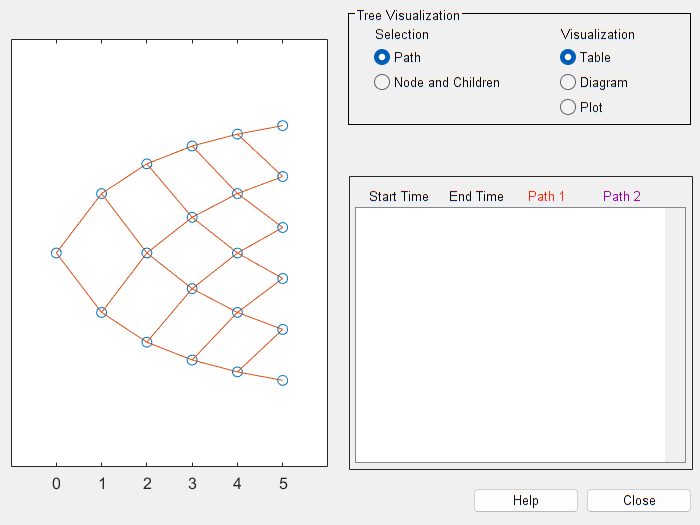

treeviewer(StockTree,St);

d) Determine the tree for the call premium Ct

OptSpec= "Call"

OptSpec = "Call"

Optionprice = optstockbycrr(StockTree,OptSpec,K,0,T)

Optionprice = 6.1836

treeviewer(StockTree,Optionprice);

uso pricing bls

call = blsprice(St,K,Rf,200/252,0.12)

call = 6.8948

deltac = blsdelta(St,K,Rf,200/252,0.12)

deltac = 0.6911